
% Record a 3-second snippet of whistling
duration = 3;  % Duration in seconds
fs = 44100;    % Sampling frequency

recObj = audiorecorder(fs, 16, 1);
disp('Start whistling...');

Start whistling...


recordblocking(recObj, duration);
disp('End of recording.');

End of recording.



% Save the recorded audio as the reference
reference_audio = getaudiodata(recObj);
audiowrite('reference_whistle.wav', reference_audio, fs);

% Load the recorded whistling audio
[recorded_audio, fs_recorded] = audioread('reference_whistle.wav');

% Compute FFT of the recorded audio
fft_result = fft(recorded_audio);

% Calculate frequency bins
freq_bins = linspace(0, fs_recorded, length(fft_result));

% Calculate magnitude spectrum
magnitude_spectrum = abs(fft_result);

% Find peaks in the magnitude spectrum
[pks, peak_indices] = findpeaks(magnitude_spectrum);

% Plot the magnitude spectrum
figure;
plot(freq_bins, magnitude_spectrum);
hold on;
plot(freq_bins(peak_indices), pks, 'ro', 'MarkerSize', 8);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Recorded Whistling');
grid on;

% Find the highest peak frequency
[~, max_peak_index] = max(pks);
fundamental_frequency_recorded = freq_bins(peak_indices(max_peak_index));

fprintf('Fundamental Frequency of Recorded Whistling: %.2f Hz\n', fundamental_frequency_recorded);

Fundamental Frequency of Recorded Whistling: 210.33 Hz


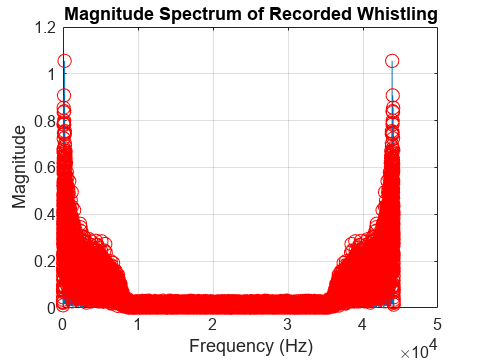

Current plot released



hold



checkAccess();

Recording...
End of recording.
ACCESS DENIED


Unrecognized function or variable 'plotSpectrum'.

Error in exp3_prob2>checkAccess (line 88)
        plotSpectrum(recorded_audio, 'Test Audio (Access Denied)' , fs);




checkAccess();


function checkAccess()
    fs = 44100;  % Sampling frequency
    
    % Record 3-second audio clip
    recObj = audiorecorder(fs, 16, 1);
    disp('Recording...');
    recordblocking(recObj, 3);
    disp('End of recording.');

    % Get the recorded audio
    recorded_audio = getaudiodata(recObj);

    
    % Calculate the fundamental frequency of the recorded audio
    fundamental_frequency_recorded = pitch(recorded_audio, fs);
    
    % Load the reference audio
    [reference_audio, fs_ref] = audioread('reference_whistle.wav');
    
    % Calculate the fundamental frequency of the reference audio
    fundamental_frequency_reference = pitch(reference_audio, fs_ref);
    
    % Define the error tolerance (5%)
    error_tolerance = 0.05 * fundamental_frequency_reference;

    
    % Compare the fundamental frequencies and provide access status
    if abs(fundamental_frequency_recorded - fundamental_frequency_reference) <= error_tolerance
        disp('ACCESS GRANTED');
        plotSpectrum(recorded_audio, 'Test Audio (Access Granted)' , fs );

    else
        disp('ACCESS DENIED');
        plotSpectrum(recorded_audio, 'Test Audio (Access Denied)' , fs);

    end
end
